addpath('Library');
z=15; %V=r^z;
E_F=1;
V=@(r,z) r.^z;

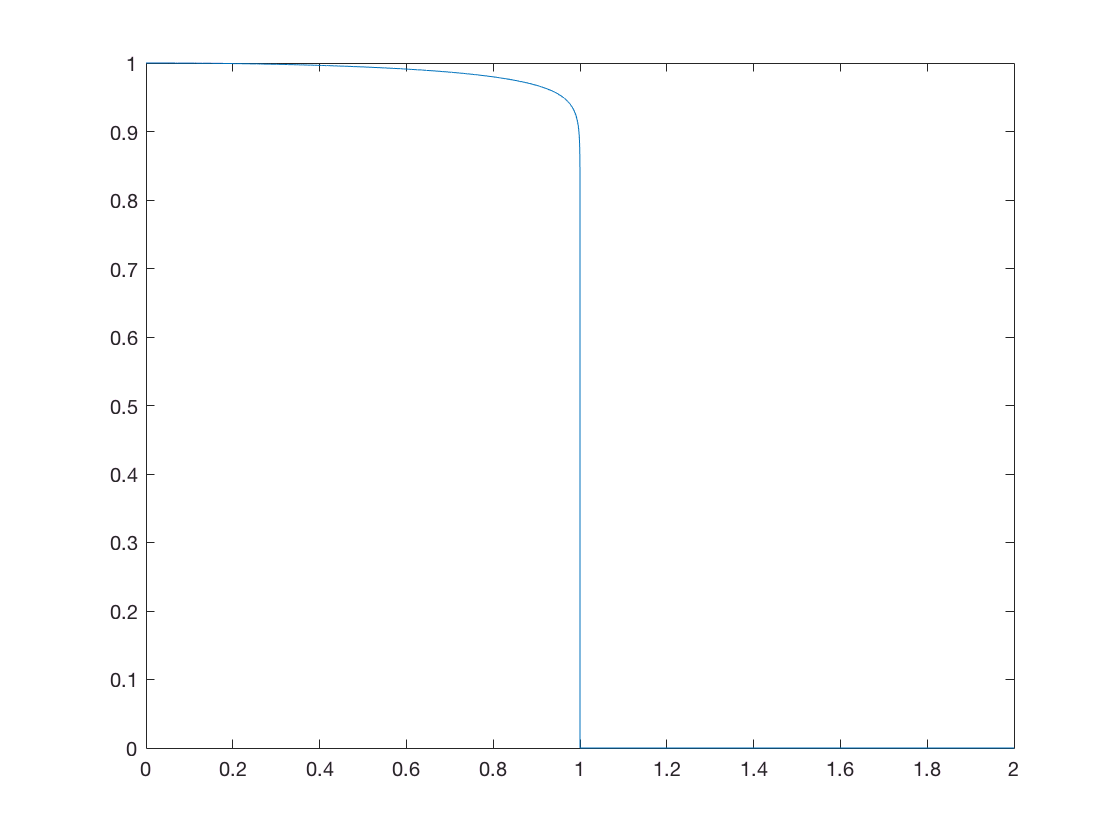

k=linspace(0,sqrt(E_F)*2,10000);
r=linspace(0,2,1000);
EF_local=max(E_F-V(r,z),0);
kF_local=sqrt(EF_local);
fk_local=@(k,kF) k<kF;
fk=trapz(k,2*pi*k*fk_local(k,kF_local));
plot(k,fk)